% Define DH parameters for each link


L1 = Prismatic('theta', -pi/2, 'a', 0, 'alpha', pi/2,'qlim', [0, 2000]); % Revolute joint (Link 1)
L2 = Revolute('d', 0, 'a', 750, 'alpha', 0);            % Revolute joint (Link 2)
L3 = Revolute('d', 0, 'a', 750, 'alpha', 0);          % Revolute joint (Link 1)
L4 = Revolute('d', 0, 'a', 750, 'alpha', 0);            % Revolute joint (Link 2)
L5 = Revolute('d', 0, 'a', 750, 'alpha', 0);          % Revolute joint (Link 1)

L6 = Revolute('d', 0, 'a', 0, 'alpha', pi/2);            % Revolute joint (Link 2)
L7 = Revolute('d', 600, 'a', 0, 'alpha', 0);  
L8 = Revolute('d', 0, 'a', 0, 'alpha', pi/2);            % Revolute joint (Link 4)
L9 = Prismatic('theta', 0, 'a', 0, 'alpha', 0,'qlim', [0.3, 1]);   
L10 = Revolute('d', 0, 'a', 0, 'alpha', -pi/2);   
L11 = Revolute('d', 0, 'a', 0, 'alpha', pi/2);   
L12 = Revolute('d', 526, 'a', 0, 'alpha', 0);   

L = [L1 L2 L3 L4 L5 L6 L7 L8 L9 L10 L11 L12];
% Combine the links into a serial-link robot
DTT_HyMan = SerialLink(L, 'name', 'DTT_HyMan');

% Predefined base transformation parameters 
 % This specifies the first link that has a length of 1m
 % And rotates the base frame to match that of the question
 base_height = 0;              % Base height along the z-axis
 base_rotation_x = pi/2;            % Rotation about the x-axis (0 radians)
 base_rotation_y = 0;            % Rotation about the y-axis (0 radians)
 base_rotation_z = pi/2;         % Rotation about the z-axis (0 degrees)

% % Set the base transformation
  DTT_HyMan.base = transl(0, 0, base_height) * ...       % Translate along z-axis
                    trotx(base_rotation_x) * ...          % Rotate about x-axis
                    troty(base_rotation_y) * ...          % Rotate about y-axis
                    trotz(base_rotation_z);               % Rotate about z-axis

% Display the robot structure
% I prefer to add this because it shows the DH table with joints and it is
% easy for me to debug any errors
DTT_HyMan.display();

 
DTT_HyMan = 
 
DTT_HyMan:: 12 axis, PRRRRRRRPRRR, stdDH, slowRNE                
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|    -1.5708|         q1|          0|     1.5708|          0|
|  2|         q2|          0|        750|          0|          0|
|  3|         q3|          0|        750|          0|          0|
|  4|         q4|          0|        750|          0|          0|
|  5|         q5|          0|        750|          0|          0|
|  6|         q6|          0|          0|     1.5708|          0|
|  7|         q7|        600|          0|          0|          0|
|  8|         q8|          0|          0|     1.5708|          0|
|  9|          0|         q9|          0|          0|          0|
| 10|        q10|          0|          0|    -1.5708|          0|
| 11|        q11|          0|          0|     1.5708|      

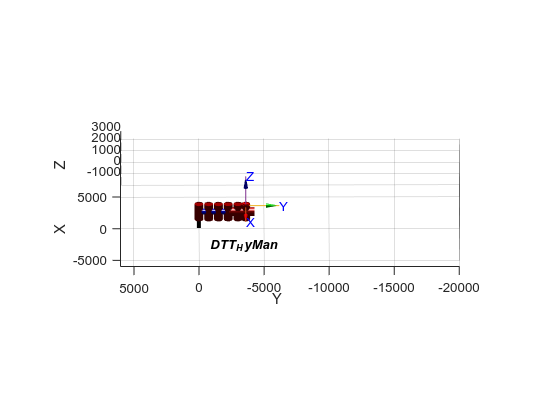


%Plot the robot with initial joint variables theta 1 =theta 2 = theta 4=0
%and d3 = 0.4
q = [3000, pi, -pi/2, -pi/2,pi/2,pi/2, 0, 0, 3000,0,0,0];

q = [0, pi/2, 0, 0,0,pi/2, 0, 0, 0,0,0,0];

DTT_HyMan.plot(q);
zlim([-1500 inf]);
ylim([-20000 inf]);

T = DTT_HyMan.fkine(q);

% Convert to a 4x4 matrix
T = T.T;

% Set very small values to zero
T(abs(T) < 1e-10) = 0;

% Display the cleaned transformation matrix
disp('Cleaned Forward Kinematics Transformation Matrix (T):');

Cleaned Forward Kinematics Transformation Matrix (T):


disp(T);

   1.0e+03 *

   -0.0010         0         0         0
         0   -0.0010         0   -3.6000
         0         0    0.0010    0.5260
         0         0         0    0.0010

